# Solution of systems of nonlinear equations

Let $f\left(x\right)$ be a vector function $R^n \longrightarrow R^n$  

The Jacobian of $f\left(x\right)$ is the $n\times n$ matrix of first partial derivatives

Both the gradient and Jacobian are "first derivatives"

- gradient: first derivative of a scalar function of several variables 

- Jacobian: first derivative of a vector function of several variables

If $f\left(x\right)$ is a scalar function $R^n \longrightarrow R$, the Jacobian is reduced to a row vector of partial derivatives of $f\left(x\right)$, i.e. the transpose of its gradient.

The Jacobian of the gradient of a scalar function of several variables is the Hessian matrix: "second derivative" of the function in question.

## Primer sistema de ecuaciones


$$x_1^2 +x_1 x_2 =10$$



$$x_2 +3x_1 x_2^2 =57$$


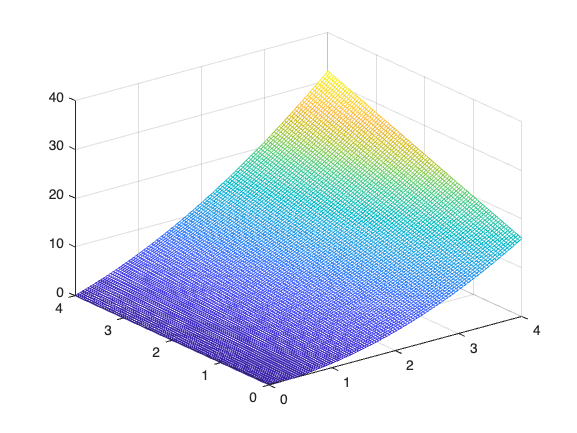

x = linspace(0,4);
y = linspace(0,4);
[X1,Y] = meshgrid(x,y);
f1 = X1.^2 + X1.*Y;
mesh(X1,Y,f1);

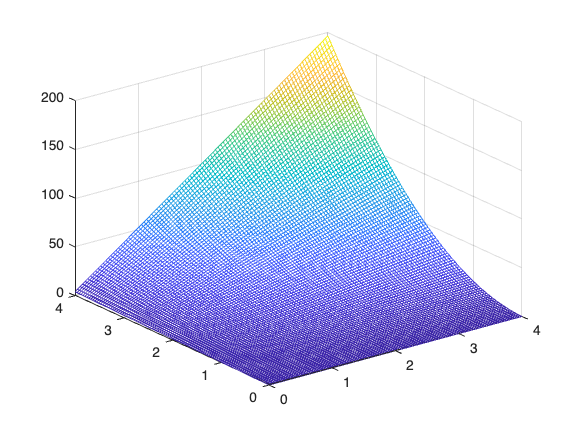

f2 = Y + 3*X1.*Y.^2;
mesh(X1,Y,f2);

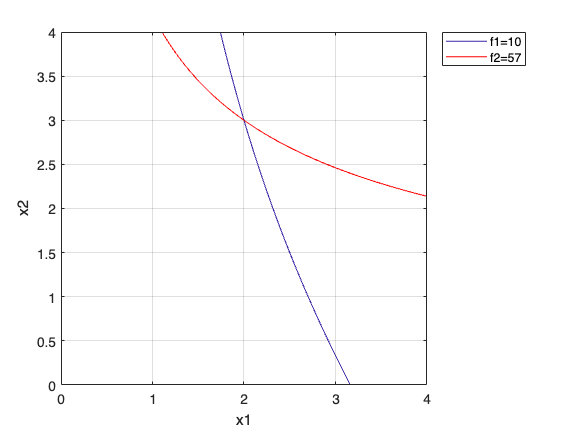

contour(X1, Y, f1,[10 10])
hold on;
contour(X1, Y, f2,[57 57],'r');
grid on;
hold off;
xlabel('x1');
ylabel('x2');
legend('f1=10','f2=57');

f = @(x) [
    x(1)^2 + x(1)*x(2) - 10;
    x(2)+ 3*x(1)*x(2)^2 - 57 ]

f = function_handle with value:
    @(x)[x(1)^2+x(1)*x(2)-10;x(2)+3*x(1)*x(2)^2-57]


J = @(x) [
    2*x(1) + x(2), x(1);
    3*x(2)^2, 1 + 6*x(1)*x(2)]

J = function_handle with value:
    @(x)[2*x(1)+x(2),x(1);3*x(2)^2,1+6*x(1)*x(2)]


disp('Newton')

Newton


x0 = [1; 1];
f(x0)

ans =     -8
   -53


[x,iter] = NewtonRaphsonVV(f,J,x0)

Unrecognized function or variable 'NewtonRaphsonVV'.

f(x)

## Segundo sistema de ecuaciones


$$3x_1 -\cos \left(x_2 x_3 \right)=\frac{3}{2}$$



$$4x_1^2 -625x_2^2 +2x_2 =1$$



$$e^{-x_1 x_2 } +20x_3 =-\frac{10\pi -3}{3}$$


%f = @(x) [3*x(1)-cos(x(2:3))-3/2;]
% J = ;
% x0 = [0; 0; 0]; 
% [x,iter] = NewtonRaphsonVV(f,J,x0)
% f(x)

## Tercer sistema de ecuaciones


$$2x_1 +x_2 +2x_3^2 \;=\;5$$



$$x_2^3 +4x_3 =4$$



$$x_1 x_2 +x_3 -e^{x_3 } =0$$


f = @(x) [2*x(1)+x(2)+2*x(3).^2-5;
    x(2).^3+4*x(3)-4;
    x(1)*x(2)+x(3)-exp^x(3)];
% J = ;
% x0 = [0; 0; 0]; 
% [x,iter] = NewtonRaphsonVV(f,J,x0)
% f(x)

## Problemas de intersección de esferas

Use Multivariate Newton’s Method to find the two points in common of the three given spheres in three-dimensional space. 

(a) Each sphere has radius 1, with centers (1,1,0), (1,0,1), and (0,1,1)

(b) Each sphere has radius 5, with centers (1,-2,0), (-2,2,-1), and (4,-2,3).

## Jacobiano simbólico

% jacobian(f,v) computes the Jacobian matrix of f with respect to v. 
% The (i,j) element of the result is df(i)/dv(j) (partial derivatives)
disp('Jacobiano simbólico')
syms x1 x2
xs = [x1;x2];
f1 = xs(1)^2 + xs(1)*xs(2) - 10;
f2 = xs(2) + 3*xs(1)*xs(2)^2 - 57;
fs = [f1; f2]
Js = jacobian(fs,xs)   

syms x1 x2 x3
xs = [x1;x2;x3];
fs = [ 3*xs(1) - cos(xs(2)*xs(3)) - 3/2  ;
  4*xs(1)^2 - 625*xs(2)^2 + 2*xs(2) - 1  ;
   exp(-xs(1)*xs(2)) + 20*xs(3) + (10*pi-3)/3]
Js = jacobian(fs,xs)

syms x1 x2 x3
xs = [x1;x2;x3];
fs = [
  2*xs(1) + xs(2) + 2*xs(3)^2 - 5 ;
  xs(2)^3 + 4*xs(3) - 4          ;
  xs(1)*xs(2) + xs(3) - exp(xs(3)) ]
Js = jacobian(fs,xs)

r=5;
syms x1 x2 x3
xs = [x1;x2;x3];
fs = [  (xs(1)-1)^2 +  (xs(2)+2)^2 + (xs(3)-0)^2 - r^2 ;
        (xs(1)+2)^2 +  (xs(2)-2)^2 + (xs(3)+1)^2 - r^2 ;
        (xs(1)-4)^2 +  (xs(2)+2)^2 + (xs(3)-3)^2 - r^2 ]
Js = jacobian(fs,xs)